# Example - Transition Dipole Moments

clear all
addpath("Molecules\");addpath("Atoms\")
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 2;
B.value = 542; %Gauss
B.dir = [0,0,1];
B.scaling = 1e-4; %to convert to Tesla
E.value = 420; %V/cm
E.dir = [0,1,0];
E.scaling = 1e2;%to convert to V/m
I.value = 0; %mW/cm^2
I.dir = [0,0,1];
I.pol = [1,0,0];
I.scaling = 1e7;%to convert to W/m^2
Fields.B = B;
Fields.E = E;
Fields.I = I;

## Define Hamiltonian

Mol = KRb(40,87);
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H = Ham.hyperfine.total + B.value*B.scaling*Ham.zeeman + I.value*I.scaling*Ham.ac_stark + E.value*E.scaling*Ham.dc_stark;
Base = Ham.Basis;
nStates = Base.NStates;

## Diagonalise

[V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
[energies,sortIdx] = sort(real(D));
states = V(:,sortIdx);
clear V D

UCBasis = Base.getStates('all');
stateIdx = 7;
stateComp = round(squeeze(states(:,stateIdx)).^2,6); %state 7 usually |-4,0.5>
[statesCompTable, ~] = sortrows([array2table(stateComp,"VariableNames","Comp") , UCBasis], "Comp","descend");
statesCompTable(1:5,:)

ans = 5×7 table
      Comp      N    mN    i1    mi1    i2     mi2 
    ________    _    __    __    ___    ___    ____

    0.998971    0    0     4     -4     1.5     0.5
     4.2e-05    0    0     4     -3     1.5    -0.5
           0    0    0     4     -4     1.5    -1.5
           0    0    0     4     -4     1.5    -0.5
           0    0    0     4     -4     1.5     1.5


initState = states(:,stateIdx)'; %row vec
Ediff = (energies - energies(stateIdx))*1e-6;%in MHz
TDM = nan(nStates,3);
for p = 1:3
    TDM(:,p) = Mol.d0/Constants.D*real(initState * Ham.dipoleOperator{p} * states); %in Debye
end

NSelect = [0,1];
selectStates = any(UCBasis.N==NSelect,2);
% TDM = TDM(selectStates,:);
% Ediff = Ediff(selectStates);
maxTDMs = max(TDM,[],2);
[~,sortIdx] = sort(maxTDMs,"descend");

sigma = char(931);
TDMTable = round(array2table([Ediff(sortIdx),TDM(sortIdx,:),sortIdx],"VariableNames",["E","s-","p","s+","StateIdx"]),4);
TDMTable(1:10,:)

ans = 10×5 table
        E          s-         p         s+       StateIdx
    _________    _______    ______    _______    ________

    2229.6268          0    0.3207          0       55   
    2229.3588     0.2266         0    -0.2341       49   
    2230.9532     0.0528         0      0.031       89   
    2230.7353          0    0.0324          0       82   
    2228.5865    -0.0437         0      0.025       37   
    2228.6711          0    0.0203          0       38   
    2231.2787      0.017         0     0.0171      100   
    2229.7298     0.0115         0    -0.0196       58   
    2231.6636     0.0103         0     0.0077      112   
     2230.075          0    0.0073          0       65   


stateComp = abs(squeeze(states(:,55))).^2; %state 7 usually |-4,0.5>
[statesCompTable, ~] = sortrows([array2table(stateComp,"VariableNames","Comp") , UCBasis(:,["N","mN","mi1","mi2"])], "Comp","descend");
round(statesCompTable(1:5,:),5)

ans = 5×5 table
     Comp      N    mN    mi1    mi2
    _______    _    __    ___    ___

    0.93721    1     0    -4     0.5
    0.02448    1    -1    -4     1.5
    0.01966    1    -1    -3     0.5
    0.01605    1     1    -3     0.5
    0.00093    1     0    -3     1.5


## Something to label states by (N,mF)_index like in Cornish?

cs = cumsum(statesCompTable.Comp);
%check number of states necessary to capture 99% of the wavefunction
reqStates = find(diff(cs > 0.99));
(statesCompTable(1:reqStates,["mN","mi1","mi2"]))

ans = 3×3 table
    mN    mi1    mi2
    __    ___    ___

     0    -4     0.5
    -1    -4     1.5
    -1    -3     0.5


(statesCompTable(1:reqStates,:))

ans = 3×5 table
           Comp           N    mN    mi1    mi2
    __________________    _    __    ___    ___

     0.937210855461511    1     0    -4     0.5
    0.0244836766873391    1    -1    -4     1.5
     0.019658106288114    1    -1    -3     0.5


## Plot Results

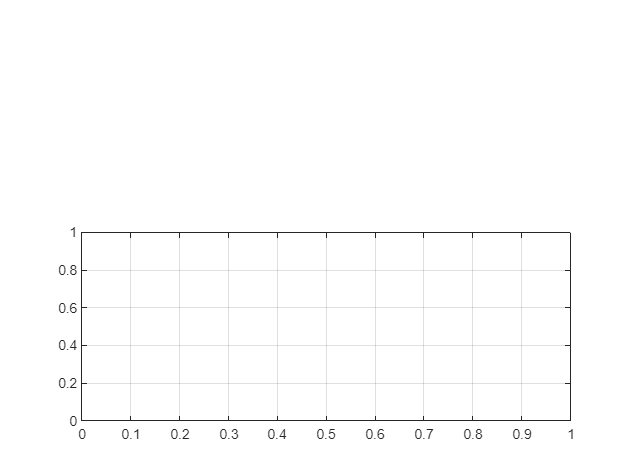

N = Base.getStates("N");
figure(12); clf;
t = tiledlayout(2,1, "TileSpacing","tight");
nexttile(2); %N=0 manifold

plot(x,energyMap(:,N==0)*1e-6, color=[1,1,1]*0.3); hold on;

Unrecognized function or variable 'x'.

xlabel("B (G)")
ylabel(sprintf("E (MHz)"))
ylim([-1.5,1])
xlim([min(x),max(x)])
axis square

nexttile(1); %N=1 manifold
plot(x,energyMap(:,N==1)*1e-6, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
xticklabels([])
ylim([978.5,981.5])
xlim([min(x),max(x)])
axis square

title(t,"Zeeman Map")
subtitle(t, sprintf("I=%.2f W/m, E=%.2f V/m", Fields.I.value,Fields.E.value))

Ham.hyperfine.total